%{
ES115 Engineering Computer Applications 
Module 1 Project: Model Selection Challenge

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 26, 2026

Purpose:
The purpose of this project is to evaluate and compare linear, quadratic, and 
piecewise mathematical structures to determine which best represents a vehicle's 
speed profile. By analyzing these candidates in MATLAB, the script selects the model 
that offers the most realistic physical behavior for simulation.

Inputs:
- Input Range (t): 0 to 20 seconds
- Step Size: 0.5 seconds
- Candidate Equations: Linear (v_{A}), Quadratic (v_{B}), and Piecewise (v_{C})

Outputs:
- Velocity Profiles: Three data vectors for comparative analysis
- Visualization: A single plot overlaying all three model candidates
- Justification Report: An engineering selection based on simplicity and realism

Engineering Workflows:
- Trade-off Analysis: Evaluating mathematical complexities versus system accuracy
- System Identification: Choosing a structure that fits expected physical behavior
- Model Validation: Using logic and continuity to justify a final design choice

MATLAB Tools:
- Logical Indexing: Creating segments for the piecewise linear model
- Vector Operations: Evaluating diverse functional forms across the time domain
- plot() and legend(): Graphing and labeling multiple datasets for visual comparison
- fprintf(): Presenting the final selection and justification
%}


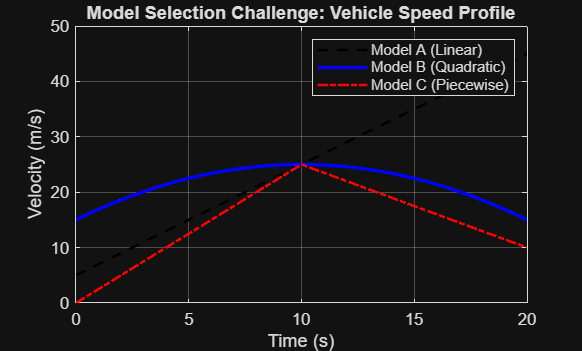

t = 0:0.5:20;

vA = 2 * t + 5;

vB = -0.1 * (t - 10).^2 + 25;

vC = zeros(size(t));
vC(t <= 10) = 2.5 * t(t <= 10);
vC(t > 10) = -1.5 * (t(t > 10) - 10) + 25;

figure;
plot(t, vA, 'k--', 'LineWidth', 1.5); hold on;
plot(t, vB, 'b-', 'LineWidth', 2);
plot(t, vC, 'r-.', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Model Selection Challenge: Vehicle Speed Profile');
legend('Model A (Linear)', 'Model B (Quadratic)', 'Model C (Piecewise)');


fprintf('Selection Criteria: Realism, Continuity, and Physical Behavior.\n');

Selection Criteria: Realism, Continuity, and Physical Behavior.


fprintf('Chosen Model: Model B (Quadratic).\n');

Chosen Model: Model B (Quadratic).


fprintf('Justification: Model B provides a smooth, continuous transition between \n');

Justification: Model B provides a smooth, continuous transition between 


fprintf('acceleration and deceleration, which better represents natural vehicle dynamics.\n');

acceleration and deceleration, which better represents natural vehicle dynamics.
